function E_map = computeScatteringLighting(K, cameraPos, cameraDir, lightPos, mesh, beta, C0, imageHeight, imageWidth)
    % 입력:
    %   K: 3x3 Intrinsic Matrix (카메라 내부 파라미터 행렬)
    %   R_link: 3x3 Rotation Matrix (월드 좌표계 -> 링크 좌표계 회전 행렬)
    %   T: 3x1 Translation Vector (월드 좌표계 -> 링크 좌표계 이동 벡터)
    %   lightPos: 1x3 광원 위치 (월드 좌표계)
    %   mesh: 메쉬 데이터 (구조체)
    %       mesh.v:  정점(Vertices) 좌표 (Nx3 행렬, N: 정점 개수)
    %       mesh.f.v: 면(Faces)을 구성하는 정점 인덱스 (Mx3 행렬, M: 면 개수)
    %       mesh.f.vn: 면의 법선 벡터 (Mx3 행렬)
    %   beta: 감쇠 계수 (Attenuation Coefficient)
    %   C0: 광원의 초기 강도 (Initial Light Intensity)
    %   imageHeight: 출력 이미지 높이
    %   imageWidth: 출력 이미지 너비

    % 출력:
    %   E_map: imageHeight x imageWidth 크기의 2D 이미지. 각 픽셀은 해당 위치에 도달하는 빛의 에너지(세기)를 나타냄.

    % 1. 메쉬 데이터 가져오기
    vertices = mesh.vertices;      % 정점 좌표
    faces_vertex = mesh.faces.v; % 면을 구성하는 정점 인덱스
    normals = mesh.faces.vn;    % 면의 법선 벡터

    % 2. 출력 맵 초기화
    E_map = zeros(imageHeight, imageWidth); % 출력 이미지를 0으로 초기화
    numFaces = size(faces_vertex, 1);     % 면의 개수

    % 3. 월드 좌표계 -> 카메라 좌표계 변환 행렬 계산
    T_link = cameraPos' % 나중에 전치 주의!!

    quat_link_world = quaternion(cameraDir(1), cameraDir(2), cameraDir(3), cameraDir(4));
    R_w2link = rotmat(quat_link_world, 'frame')         % 월드 -> 링크 좌표계 회전
    R_link2cam =[0 -1 0; 0 0 -1; 1 0 0];                % 링크 좌표계 -> 카메라 좌표계 회전 
    
    Proj_w2link = [R_w2link, -R_w2link*T_link; 0,0,0,1];        % 동차 변환 행렬 (월드 -> 링크)
    Proj_link2Cam = [R_link2cam, zeros(3,1); zeros(1,3), 1];    % 동차 변환 행렬 (링크 -> 카메라)
    Proj_w2cam = Proj_link2Cam * Proj_w2link;                   % 동차 변환 행렬 (월드 -> 카메라)

    % 4. 광원 위치를 카메라 좌표계로 변환 (동차 좌표계 사용)
    lightPos_hom = [lightPos, 1]'; % 광원 위치를 동차 좌표로
    lightPosCam_hom = Proj_w2cam * lightPos_hom;
    lightPosCam = lightPosCam_hom(1:3); % 다시 3차원 좌표로

    % ******************** 시각화 (추가) ********************
    figure;
    
    % 1. 메쉬 그리기
    subplot(1, 2, 1);
    trisurf(faces_vertex, vertices(:,1), vertices(:,2), vertices(:,3), 'FaceColor', 'cyan', 'EdgeColor', 'k');
    hold on;

    % Face 중앙에 Face 번호 표시
    for i = 1:size(mesh.faces.v, 1)
        % 현재 Face의 정점 3개 가져오기
        face_vertices = vertices(faces_vertex(i, :), :);
        
        % Face의 중심 좌표 계산
        face_center = mean(face_vertices, 1);
        
        % Face의 중앙에 번호 표시
        text(face_center(1), face_center(2), face_center(3), num2str(i), ...
            'FontSize', 12, 'FontWeight', 'bold', 'Color', 'r');
    end
    
    % 2. 카메라 위치 및 방향 (월드 좌표계)
    cameraPos_world = cameraPos; % 월드 좌표계에서의 카메라 위치 (링크 좌표계 원점)
    R_world_to_cam = R_link2cam * R_w2link;
     % 카메라 X축 (Right) - 빨강
    quiver3(cameraPos_world(1), cameraPos_world(2), cameraPos_world(3), R_world_to_cam(1,1), R_world_to_cam(2,1), R_world_to_cam(3,1), 0.3 ,'r', 'LineWidth', 2, 'MaxHeadSize', 0.5);
    % 카메라 Y축 (Down) - 초록
    quiver3(cameraPos_world(1), cameraPos_world(2), cameraPos_world(3), R_world_to_cam(1,2), R_world_to_cam(2,2), R_world_to_cam(3,2), 0.3 ,'g', 'LineWidth', 2, 'MaxHeadSize', 0.5);
    % 카메라 Z축 (Forward) - 파랑
    quiver3(cameraPos_world(1), cameraPos_world(2), cameraPos_world(3), R_world_to_cam(1,3), R_world_to_cam(2,3), R_world_to_cam(3,3), 0.3 ,'b','LineWidth', 2, 'MaxHeadSize', 0.5);
    
    plot3(cameraPos_world(1), cameraPos_world(2), cameraPos_world(3), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % 카메라 위치 (빨간색 점)

    % 3. 광원 위치
    plot3(lightPos(1), lightPos(2), lightPos(3), 'yo', 'MarkerSize', 10, 'MarkerFaceColor', 'y'); % 노란색 점
    
    % 축 및 레이블
    xlabel('X (World)');
    ylabel('Y (World)');
    zlabel('Z (World)');
    title('World Coordinate System (Mesh, Camera, Light)');
    axis equal;
    grid on;
    view(3);    
    hold off;

    % ******************************************************


    
   % 5. 각 면에 대해 반복
    for i = 1:numFaces
        % 5.1. 면의 세 정점 좌표 (월드 좌표계)
        v1 = vertices(faces_vertex(i, 1), :); % 첫 번째 정점
        v2 = vertices(faces_vertex(i, 2), :); % 두 번째 정점
        v3 = vertices(faces_vertex(i, 3), :); % 세 번째 정점

        % 5.2. 면 중심 (월드 좌표계)
        faceCenter = (v1 + v2 + v3) / 3;

        % 5.3. 면의 법선 벡터 (월드 좌표계, 정규화)
        normal = normals(i, :);
        normal = normal / norm(normal);

        % 5.4. 카메라 좌표계로 변환 (동차 좌표계 사용)
        faceCenter_hom = [faceCenter, 1]';
        faceCenterCam_hom = Proj_w2cam * faceCenter_hom;
        faceCenterCam = faceCenterCam_hom(1:3);

        v1_hom = [v1, 1]';
        v1_cam_hom = Proj_w2cam * v1_hom;
        v1_cam = v1_cam_hom(1:3);

        v2_hom = [v2, 1]';
        v2_cam_hom = Proj_w2cam * v2_hom;
        v2_cam = v2_cam_hom(1:3);

        v3_hom = [v3, 1]';
        v3_cam_hom = Proj_w2cam * v3_hom;
        v3_cam = v3_cam_hom(1:3);

        normal_hom = [normal, 0]'; % 방향 벡터는 마지막 요소가 0
        normalCam_hom = Proj_w2cam * normal_hom;
        normalCam = normalCam_hom(1:3);



        % 5.5. 광원 방향 (카메라 좌표계)
        lightDir = lightPosCam - faceCenterCam; % 면 중심 -> 광원
        lLS = norm(lightDir);              % 광원과 면 중심 사이의 거리
        lightDir = lightDir / lLS;           % 정규화

        % 5.6. Lambertian 반사 계수
        diffuseFactor = max(0, dot(normalCam, lightDir)); % (0 ~ 1)

        % 5.7. 직접광 (Ds) 계산
        Ds = (C0 * exp(-beta * lLS)) / (lLS^2);

        % 5.8. 산란 지점 (z) 계산 (카메라 좌표계)
        epsilon = 0.01; % 작은 값 (면에서 약간 떨어진 거리)
        z = faceCenterCam + epsilon * normalCam; % 면 중심에서 법선 방향으로

        % 5.9. 거리 계산 (카메라 좌표계)
        lLZ = norm(lightPosCam - z);     % 광원 -> 산란 지점
        lSZ = norm(z - faceCenterCam);   % 산란 지점 -> 면 중심
        lSC = norm(faceCenterCam);       % 면 중심 -> 카메라

        % 5.10. 산란광 (As) 계산
        As = (C0 * exp(-beta * (lLZ + lSZ))) / ((lLZ + lSZ)^2);

        % 5.11. 초기 조도, 최종 조도
        Es_initial = Ds + As;            % 직접광 + 산란광
        Es = Es_initial * exp(-beta * lSC); % 최종 감쇠

        % 5.12. 각 정점을 2D 이미지 좌표로 투영 (카메라 내부 파라미터 K 사용)
        v1_proj_hom = K * v1_cam;
        v1_proj = round(v1_proj_hom(1:2) / v1_proj_hom(3)); % 2D 픽셀 좌표

        v2_proj_hom = K * v2_cam;
        v2_proj = round(v2_proj_hom(1:2) / v2_proj_hom(3));

        v3_proj_hom = K * v3_cam;
        v3_proj = round(v3_proj_hom(1:2) / v3_proj_hom(3));


        % 5.13. 삼각형 래스터화 (Bresenham's Algorithm 기반)
        pixels = [];

        % 삼각형의 세 변을 따라 픽셀 좌표 생성
        pixels = [pixels; bresenham(v1_proj(1), v1_proj(2), v2_proj(1), v2_proj(2))];
        pixels = [pixels; bresenham(v2_proj(1), v2_proj(2), v3_proj(1), v3_proj(2))];
        pixels = [pixels; bresenham(v3_proj(1), v3_proj(2), v1_proj(1), v1_proj(2))];

        % 5.14. 삼각형 내부 픽셀에 대해 반복
        for p = 1:size(pixels, 1)
             x = pixels(p, 1); % 픽셀 x 좌표
             y = pixels(p, 2); % 픽셀 y 좌표

             % 픽셀이 이미지 범위 내에 있는지 확인
            if x < 1 || x > imageWidth || y < 1 || y > imageHeight
                continue;
            end

            % Barycentric Coordinates 계산
            [alpha, beta, gamma] = barycentric(x, y, v1_proj, v2_proj, v3_proj);

            if alpha >= 0 && beta >= 0 && gamma >= 0
                % 5.15. 픽셀 (x, y)에 E_s * diffuseFactor 값을 할당
                E_map(y, x) = Es * diffuseFactor;
            end
        end
    end % for i

    % ******************************************************
    figure;
    imagesc(E_map);
    colorbar;
    title('E\_map (Scattering Lighting)');
    xlabel('Pixel X');
    ylabel('Pixel Y');
    axis image; % x, y 축 비율을 데이터에 맞게
    % ******************************************************
end % function

% Bresenham's line algorithm 함수
function points = bresenham(x1, y1, x2, y2)
    % 입력: 두 점 (x1, y1), (x2, y2)
    % 출력: 두 점을 잇는 직선 상의 픽셀 좌표 (정수)

    points = [];
    dx = abs(x2 - x1);
    dy = abs(y2 - y1);
    sx = sign(x2 - x1);
    sy = sign(y2 - y1);
    err = dx - dy;

    x = x1;
    y = y1;

    while true
        points = [points; x, y];

        if x == x2 && y == y2
            break;
        end

        e2 = 2 * err;
        if e2 > -dy
            err = err - dy;
            x = x + sx;
        end
        if e2 < dx
            err = err + dx;
            y = y + sy;
        end
    end
end

% Barycentric coordinates 계산 함수
function [alpha, beta, gamma] = barycentric(x, y, v1, v2, v3)
    % 입력:
    %   x, y: 픽셀 좌표
    %   v1, v2, v3: 삼각형의 세 꼭지점 좌표 (2D)
    % 출력:
    %    alpha, beta, gamma: Barycentric Coordinates

    % 삼각형 면적 계산 (두 벡터의 외적)
    area = 0.5 * (-v2(2) * v3(1) + v1(2) * (-v2(1) + v3(1)) + v1(1) * (v2(2) - v3(2)) + v2(1) * v3(2));

    % 각 꼭지점에 대한 가중치 계산
    alpha = 0.5 * (-v2(2) * v3(1) + y * (-v2(1) + v3(1)) + x * (v2(2) - v3(2)) + v2(1) * v3(2)) / area;
    beta  = 0.5 * ( v1(2) * v3(1) - y * v3(1) + x * (-v1(2) + v3(2)) - v1(1) * v3(2)              ) / area;
    gamma = 0.5 * (-v1(2) * v2(1) + v1(2) * x + v2(2) * (-x + v1(1)) + y * (v2(1) - v1(1))) / area;

end

function viz_scene(mesh, cameraPos, cameraDir, lightPos)
    mesh
    cameraPos
    % cameraDir = cameraDir'
    lightPos

    persistent figHandle; % Figure 핸들을 저장할 persistent 변수

    if isempty(figHandle)
        % Figure가 없으면 (처음 실행) figHandle 초기화
        figHandle = figure;
        set(figHandle, 'Name', 'Scene Visualization'); % (선택 사항) 창 제목 설정
    elseif ~ishandle(figHandle) || ~strcmp(get(figHandle, 'Type'), 'figure')
        % Figure 핸들이 유효하지 않으면 (Figure가 닫힌 경우)
        figHandle = figure; % 새 Figure 생성
        set(figHandle, 'Name', 'Scene Visualization');
    end
    
    figure(figHandle); % 해당 Figure를 활성화
    clf;    % Figure 내용 clear  % clf(figHandle) 대신 clf 사용

    faces_vertex = mesh.faces.v;
    vertices = mesh.vertices;
    quat_link_world = quaternion(cameraDir(1), cameraDir(2), cameraDir(3), cameraDir(4));
    R_w2link = rotmat(quat_link_world, 'frame')         % 월드 -> 링크 좌표계 회전
    R_link2cam =[0 -1 0; 0 0 -1; 1 0 0]';                % 링크 좌표계 -> 카메라 좌표계 회전


    % 1. 메쉬 그리기
    subplot(1, 2, 1); % 이 부분은 그대로 유지
    trisurf(faces_vertex, vertices(:,1), vertices(:,2), vertices(:,3), 'FaceColor', 'cyan', 'EdgeColor', 'k');
    hold on;
    % Face 중앙에 Face 번호 표시
    for i = 1:int32(size(faces_vertex, 1))
        % 현재 Face의 정점 3개 가져오기
        face_vertices = vertices(faces_vertex(i, :), :);

        % Face의 중심 좌표 계산
        face_center = mean(face_vertices, 1);

        % Face의 중앙에 번호 표시
        text(face_center(1), face_center(2), face_center(3), sprintf('%d',i), ...
            'FontSize', 12, 'FontWeight', 'bold', 'Color', 'r');
    end

    % 2. 카메라 위치 및 방향 (월드 좌표계)
    cameraPos_world = cameraPos; % 월드 좌표계에서의 카메라 위치
    R_world_to_cam = R_link2cam * R_w2link % 카메라 방향 변환 행렬
    % 카메라 X축 (빨강)
    quiver3(cameraPos_world(1), cameraPos_world(2), cameraPos_world(3), ...
        R_world_to_cam(1,1), R_world_to_cam(2,1), R_world_to_cam(3,1), 0.3, 'r', 'LineWidth', 2, 'MaxHeadSize', 0.5);
    % 카메라 Y축 (초록)
    quiver3(cameraPos_world(1), cameraPos_world(2), cameraPos_world(3), ...
        R_world_to_cam(1,2), R_world_to_cam(2,2), R_world_to_cam(3,2), 0.3, 'g', 'LineWidth', 2, 'MaxHeadSize', 0.5);
    % 카메라 Z축 (파랑)
    quiver3(cameraPos_world(1), cameraPos_world(2), cameraPos_world(3), ...
        R_world_to_cam(1,3), R_world_to_cam(2,3), R_world_to_cam(3,3), 0.3, 'b', 'LineWidth', 2, 'MaxHeadSize', 0.5);

    % 카메라 위치 (빨간색 점)
    plot3(cameraPos_world(1), cameraPos_world(2), cameraPos_world(3), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    % 3. 광원 위치
    plot3(lightPos(1), lightPos(2), lightPos(3), 'yo', 'MarkerSize', 10, 'MarkerFaceColor', 'y'); % 노란색 점
    % 축 및 레이블
    xlabel('X (World)');
    ylabel('Y (World)');
    zlabel('Z (World)');
    title('World Coordinate System (Mesh, Camera, Light)');
    axis equal;
    grid on;
    view(3);
    hold off;
end

mesh = struct with fields:
     vertices: [8×3 double]
        faces: [1×1 struct]
    uv_coords: [24×2 double]


cameraPos =      0     0     1


lightPos =          0    0.1000    1.0000


R_w2link =      1     0     0
     0     1     0
     0     0     1


R_world_to_cam =      0     0     1
    -1     0     0
     0    -1     0


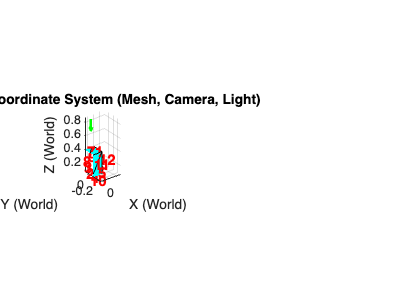

% run('code_params.m');

cameraPos = [0, 0, 1];
cameraDir = [1, 0, 0, 0];
lightPos = [0, 0.1, 1];

imageHeight = 480;
imageWidth = 640;

% 3. 함수 실행
% E_map = computeScatteringLighting(K, cameraPos, cameraDir, lightPos, mesh_data, beta, C0, imageHeight, imageWidth);
viz_scene(mesh_data, cameraPos, cameraDir, lightPos)

% --- 결과 시각화 및 검증 ---

% imwrite(E_map, 'data/test_E_map.png');

% 4. E_map 시각화


cameraDir_arr = [0.70711, 0, 0.70711, 0];
cameraDir_quat = quaternion(0.70711, 0, 0.70711, 0)
cameraDir_quat = quaternion(cameraDir_arr(1), cameraDir_arr(2), cameraDir_arr(3), cameraDir_arr(4))

% R_rotm = rotmat(cameraDir_quat, 'frame')
% R_rotm = rotmat(cameraDir_arr, 'frame')
% R_test = quat2rotm(cameraDir_quat)'
% R_test_ = quat2rotm(cameraDir_arr)'